# Figure S5B

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';
    load([dataDir filesep 'A076_data.mat'],'S','settings','allIF');

conditions = settings.conditions;


framesPerHr = 60/12;
 frameDrugAdded =0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,2)),1);
    apcGateAll = false(length(dat.POI(:,2)),1); 
     crlGate = false(length(dat.POI(:,3)),1);

    for n = 1:length(dat.POI(:,1))
      if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .2 & ...
                nanmean(dat.apcNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .02;
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) <numFrames - 1 * framesPerHr
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,1) - 1 * framesPerHr) >  .5 & ...
               dat.crlNormAct(n,dat.POI(n,1) + 1 * framesPerHr) > .5;
        end


    end
    
    S(i).apcExpressGate = apcExpressGate;
        S(i).apcGate = apcGate;
S(i).apcGateAll = apcGateAll;

   S(i).crlGate = crlGate;


end

S5B left


conds=[10 1];
timeGate = [0 20];
colors = [.5 .5 .5;.6 .9 .2;.1 .4 1;  .5 .1 .702;.8 .2 .6;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) &...
        S(conds(i)).crlGate &...
        S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate;
    sum(inds)
    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;

    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5});
end

ans = 237

ans = 125

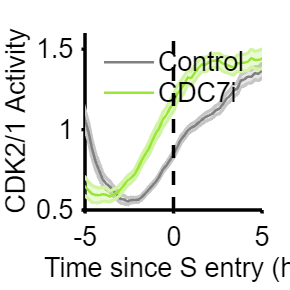


ylabel({'CDK2/1 Activity'});xlabel('Time since S entry (h)');
legend('Control','CDC7i','box','off','Location','north','fontsize',16);

xlim([-5 5]); 
ylim([.5 1.6]);
vline([0],'k--')

% print_pdf('Fig_S5B_left.pdf')

S5B right


colors = [.5 .5 .5;.6 .9 .2;.1 .4 1;  .5 .1 .702;.8 .2 .6;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
f1 = figure('unit','inches','position',[0 0 4 4]);
conds=[10 1];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 20];
 
for i=1:length(conds)
    c = conds(i);
    data = S(c);
     inds = ~isnan(S(conds(i)).POI(:,POI_align)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) &...
        S(conds(i)).crlGate &...
        S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate;

 sum(inds)

    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
 
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];


end

ans = 237

ans = 125

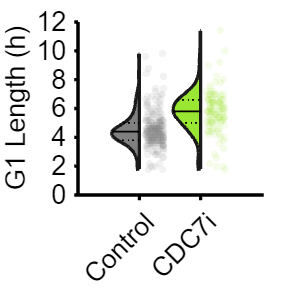

figure(f1);
  cols = repmat({colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([colors([1 2 ],:)],1,1);
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',1,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',2)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally),20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 Length (h)'])
xticklabels({'Control','CDC7i'});

% hline(0,'k')

 yticks(0:2:12)
xtickangle(45)
ylim([0 12])
set(gca, 'color','white','XColor','black','Ycolor','black','fontsize',16)
hold off

median_test1 =mediantest(ally(groups==1),ally(groups==2))

median_test1 = 3.1589e-19

% print_pdf('Fig_S5B_right.pdf')